syms t theta omega real

x_sym = [
    theta
    omega
    ]

$$x\_sym = \left(\begin{array}{c} \theta \\ \omega \end{array}\right)$$

b = 1;
f = [
    omega % dot theta
    -b*omega - sin(theta) % dot omega
    ];
f_ode = matlabFunction(f,'Vars',{t,x_sym});

f_fh = @(~,x) [
    x(2)
    -b*x(2) - sin(x(1))
    ];


Simulate an ODE

T = 10;
x0 = [-pi;0.1];
[t,x] = ode45(f_fh,[0 T],x0)

t =          0
    0.0502
    0.1005
    0.1507
    0.2010
    0.3352
    0.4694
    0.6036
    0.7378
    0.8706


x =    -3.1416    0.1000
   -3.1367    0.0952
   -3.1320    0.0909
   -3.1275    0.0870
   -3.1233    0.0836
   -3.1126    0.0761
   -3.1027    0.0708
   -3.0935    0.0674
   -3.0846    0.0655
   -3.0759    0.0650


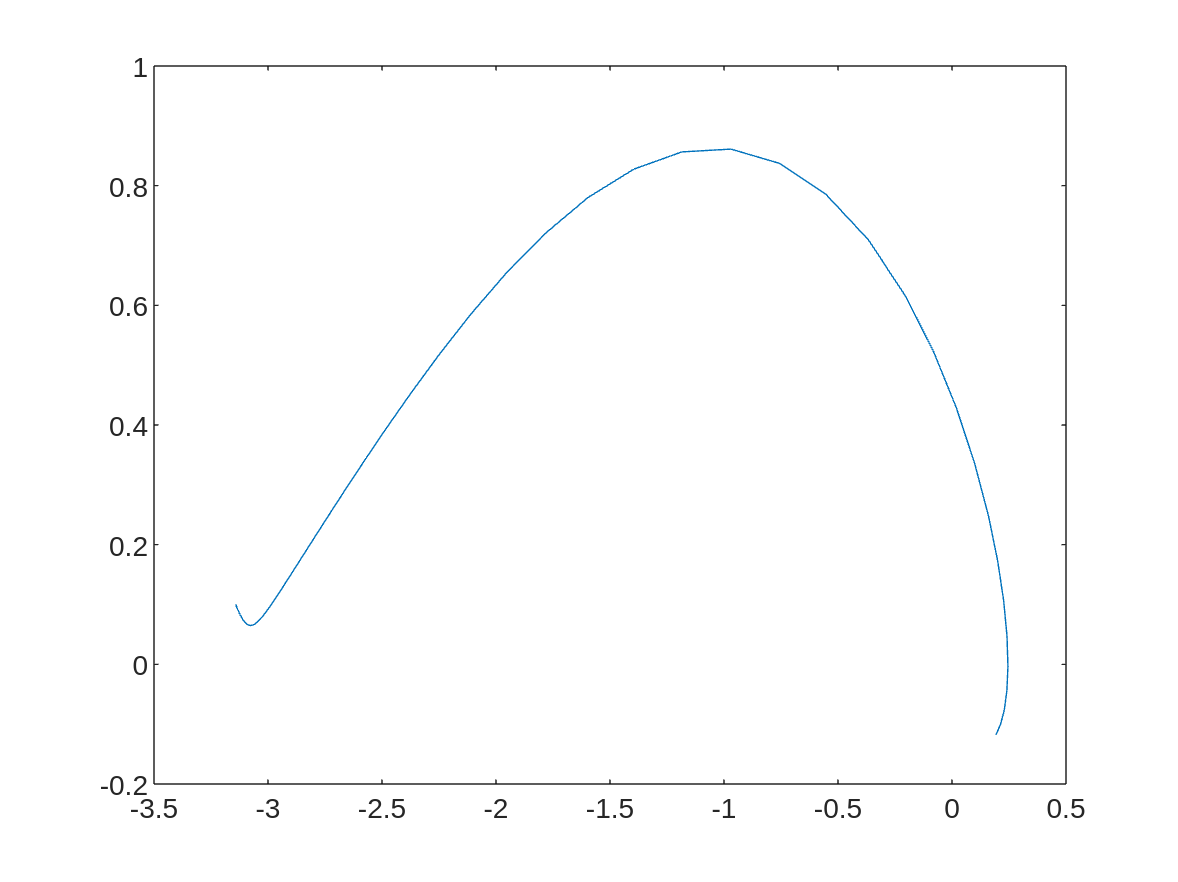

plot(x(:,1),x(:,2))

Plot the energy function

E = omega^2/2 + (1 - cos(theta))

$$E = \frac{\omega^{2}}{2}-\cos\left(\theta \right)+1$$

E_fh = matlabFunction(E,'vars',x_sym)

E_fh = function_handle with value:
    @(theta,omega)-cos(theta)+omega.^2./2.0+1.0

x_sym

$$x\_sym = \left(\begin{array}{c} \theta \\ \omega \end{array}\right)$$

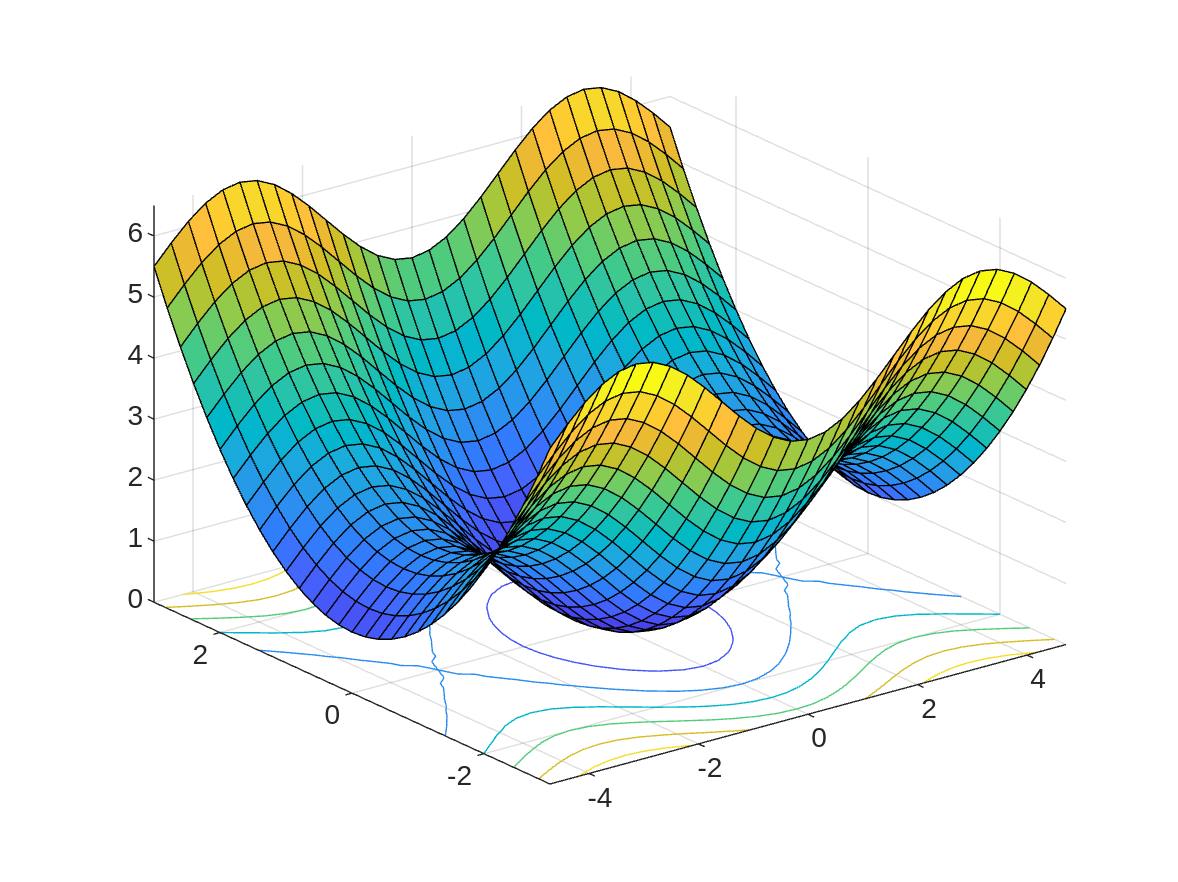

[x1_mesh,x2_mesh] = meshgrid(linspace(-1.5*pi,1.5*pi,31),linspace(-3,3,31));
E_mesh = E_fh(x1_mesh,x2_mesh);
surf(x1_mesh,x2_mesh,E_mesh), hold on
contour(x1_mesh,x2_mesh,E_mesh)

Visualize the vector field of the dynamical model

f1_fh = matlabFunction(f(1),'vars',x_sym)

f1_fh = function_handle with value:
    @(theta,omega)omega

f2_fh = matlabFunction(f(2),'vars',x_sym)

f2_fh = function_handle with value:
    @(theta,omega)-omega-sin(theta)

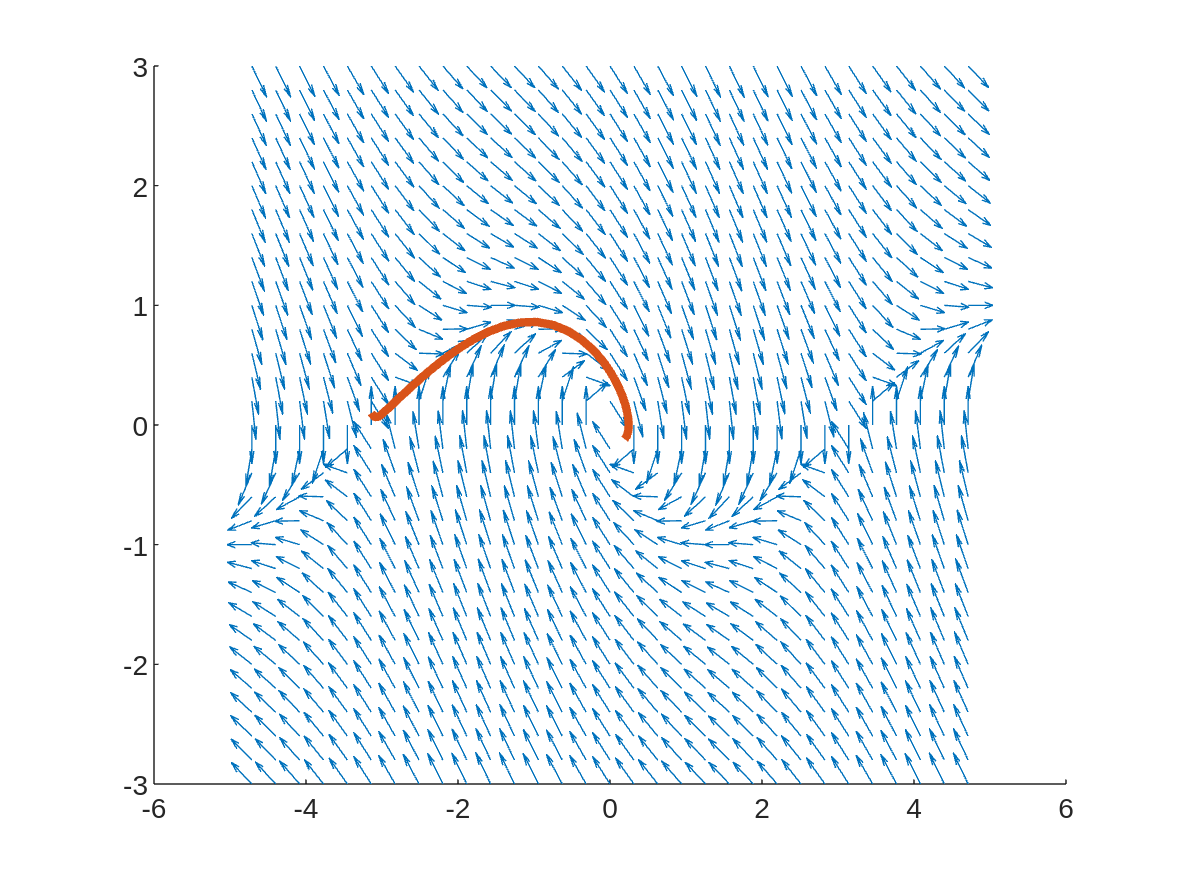


f1_num = f1_fh(x1_mesh,x2_mesh);
f2_num = f2_fh(x1_mesh,x2_mesh);

r = sqrt(f1_num.^2 + f2_num.^2);

f1_num = f1_num ./ r;
f2_num = f2_num ./ r;

figure, hold on
quiver(x1_mesh,x2_mesh,f1_num,f2_num)
plot(x(:,1),x(:,2),'LineWidth',3)